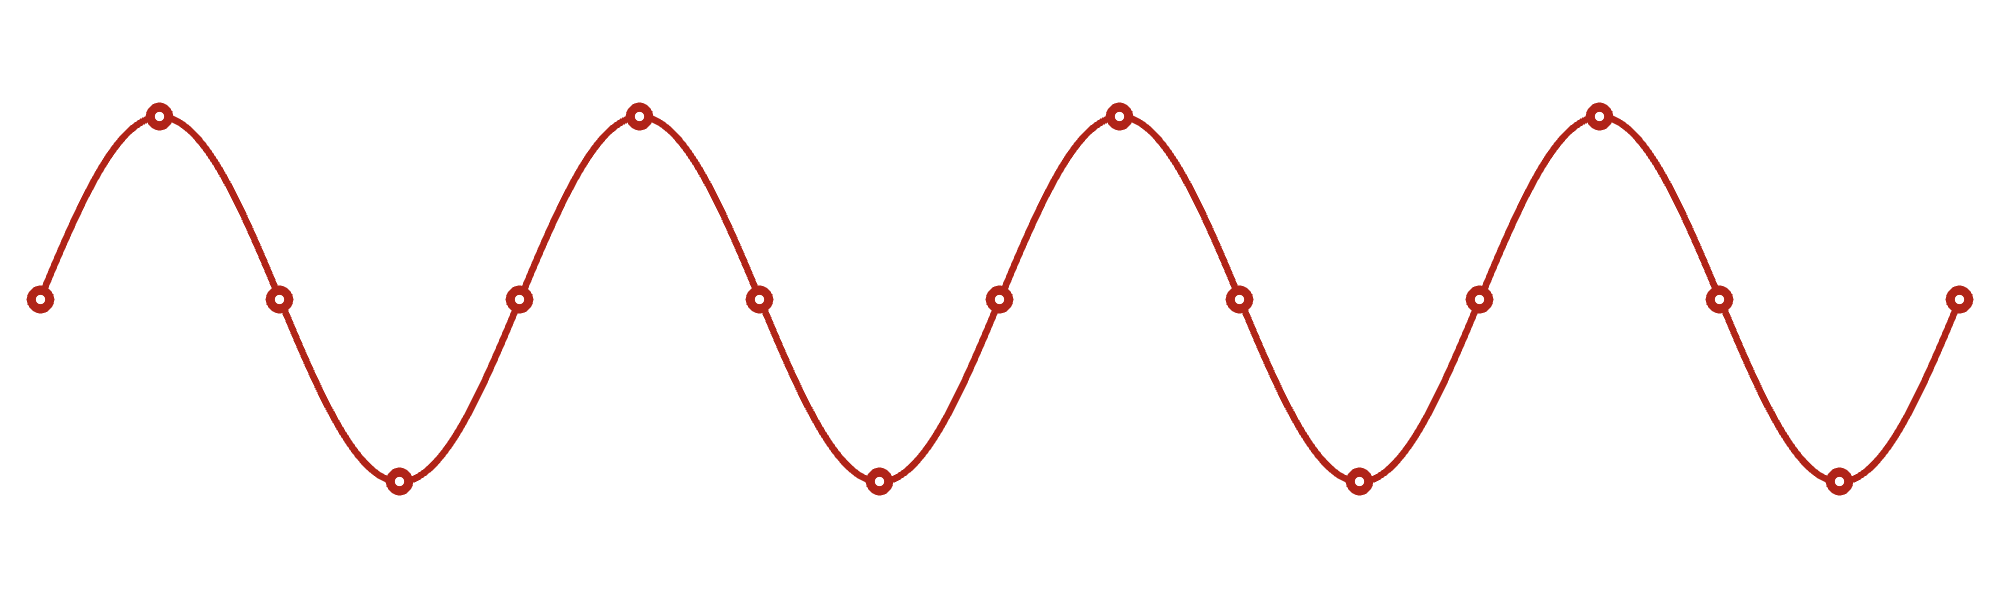

%% Clean 4-period sinusoid with 57 sampled points
clc; clear; close all;

% Continuous wave (4 periods)
x = linspace(0, 8*pi, 2000);   % 4 periods = 8*pi radians
y = sin(x);

% Sampled points
x_s = linspace(0, 8*pi, 17);
y_s = sin(x_s);

myRed = [176 36 24]/255;

%% Figure
figure('Color','w','Units','pixels','Position',[100 100 1000 300]);
hold on;

% Continuous sinusoid
plot(x, y, 'Color', myRed, 'LineWidth', 2.5);

% Sample locations
plot(x_s, y_s, 'o', ...
    'MarkerSize', 7, ...
    'MarkerFaceColor', 'w', ...
    'MarkerEdgeColor', myRed, ...
    'LineWidth', 3.5);

% Clean appearance
axis tight;
axis off;
box off;

% Optional small margins
xlim([min(x) max(x)]);
ylim([-1.15 1.15]);

set(gca,'Position',[0.02 0.15 0.96 0.70]);

exportgraphics(gcf,'FourPeriodSinusoid_57Samples.png','Resolution',300);